# Producto Matriz Robusto

k=0;
A = [1,2,3;3,4,5;4,5,6];

A =      1     2     3
     3     4     5
     4     5     6


B = [4,3;2,1;3,1+k];

B =      4     3
     2     1
     3     1


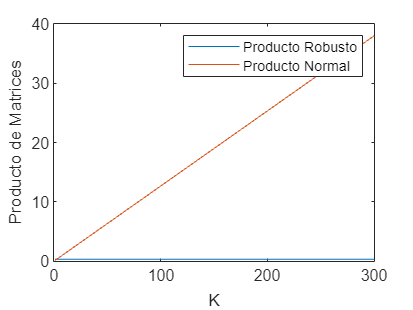

%A*B
% Producto Robusto
x = 1:300;
y1 = zeros(1,300);
y2 = zeros(1,300);
C = A*B;
%C_mod = robust_product(A,B_mod)

C_original = robust_product(A,B);
for k = x
    B_mod = [4,3;2,1;3,1+k];
    C_mod = robust_product(A,B_mod);

    D_og = C - A*B_mod;
    D_robust = C_original-C_mod;
    y1(1,k) = norm(D_robust,"fro")/norm(C_original,"fro");
    y2(1,k) = norm(D_og,"fro")/norm(C,"fro");
end

plot(x,y1)
hold on
plot(x,y2)
legend('Producto Robusto', 'Producto Normal')
xlabel('K')
ylabel('Producto de Matrices')
hold off

function [matrix] = robust_product(A,B)
    [rows_a, cols_a] = size(A);
    [~, cols_b]  = size(B);
    robust = zeros(rows_a,cols_b);
    product = zeros(1,cols_a);
    n = cols_a;
    for i = 1:rows_a
        for j = 1:cols_b
            for k = 1:cols_a
                product(1,k) = A(i,k)*B(k,j);
            end
            robust(i,j) = n*median(product);
            product = zeros(1,cols_a);
        end

    end
    matrix = robust;
end